**Cystinosis Disease Detector**

Loading the data:

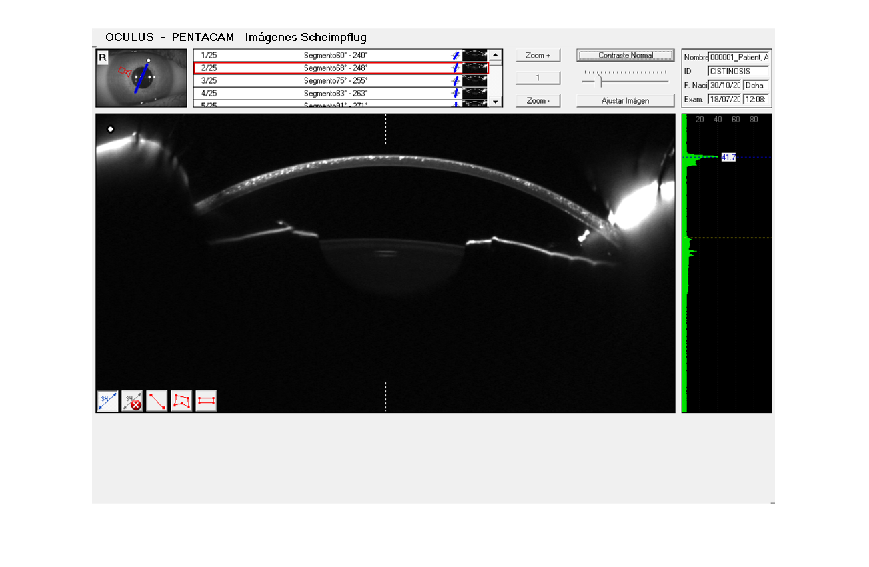

I = imread( '../data/OD1con_Cistinosis/CISTINOSIS_20160718_120806_PENTACAM_R_02.BMP' );
figure,
imshow( I );

Pre-processing: 

I = rgb2gray(I);
I = imcrop( I,[0, 130, 870, 410] );

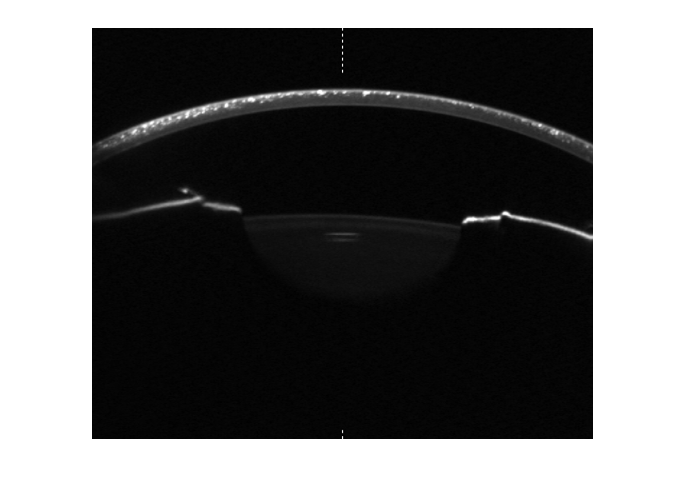

%getting the first 10 rows
croped = imcrop( I, [0, 0, size(I,2), 10] );
bin = imbinarize( croped,0.35 );
%finding the eye center
[row, column] = find( bin, 1, 'last');
%creating a ROI
I = imcrop(I, [column-250, 0 , 250*2, size(I,1)]);
imshow( I );

Localització dels objectes: segmentar la imatge original per diferenciar els objectes d’interès.

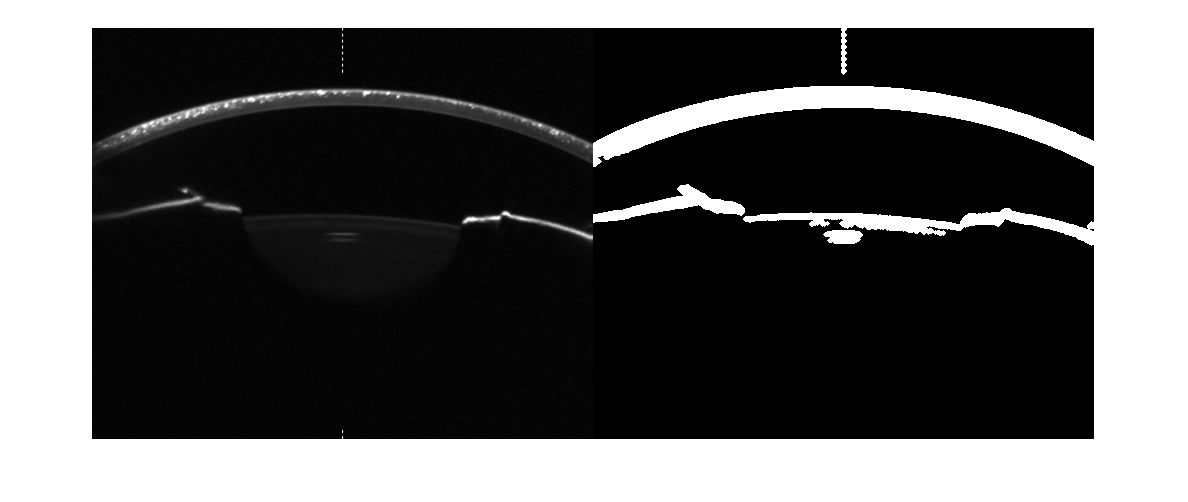

%localitzem la cornia
se = strel( 'disk', 2 );
threshold = 0.1;
I_pin_b = imbinarize( I, threshold );
I_pin_b = imdilate( I_pin_b, se );
I_pin_b = imfill( I_pin_b,'holes');
I_pin_b = bwareaopen( I_pin_b, 60 );
figure,
imshowpair( I, I_pin_b, 'montage' );   

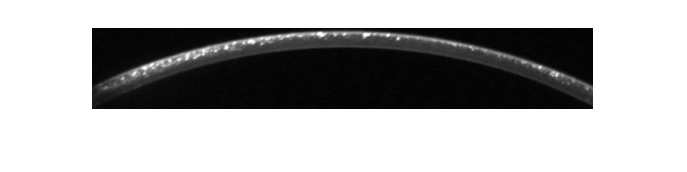

% Apply regionprops to the binary mask
s = regionprops( I_pin_b, 'BoundingBox');
%// Get the bounding box property
bb = floor( s(1).BoundingBox );
%// Extract out the object from the segmented image and place in cell array
cornea = I( bb(2)+1:bb(2)+bb(4), bb(1)+1:bb(1)+bb(3) );
figure,
imshow( cornea )

Aplanem la cornea

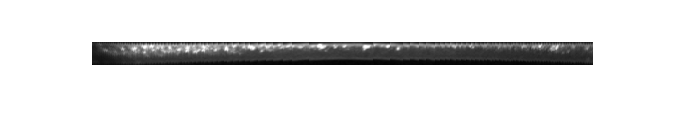

cornea_bin = imbinarize(cornea, threshold);
[rows, cols] = size( cornea );

for j = 1:cols
    i = 1;
    new_i = 1;
    while cornea_bin(i,j) < 1
        i=i+1;
    end
    for i = i:rows
        cornea(new_i,j) = cornea(i,j);
        cornea(i,j) = 0;
        new_i = new_i+1;
    end
end

I_pin_b = imbinarize( cornea, threshold );
s = regionprops( I_pin_b, 'BoundingBox');
bb = floor( s(1).BoundingBox );
cornea = cornea( bb(2)+1:bb(2)+bb(4), bb(1)+1:bb(1)+bb(3) );
imshow( cornea );

Distingim els cristalls respecte la resta de la imatge mitjaçant una binarització

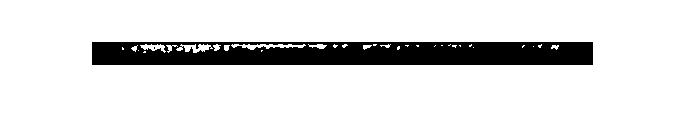

crystals = imbinarize( cornea, 0.625 );
figure,
imshow( crystals);

Amb la informació extreta de la imatge realitzar la tasca demanada.

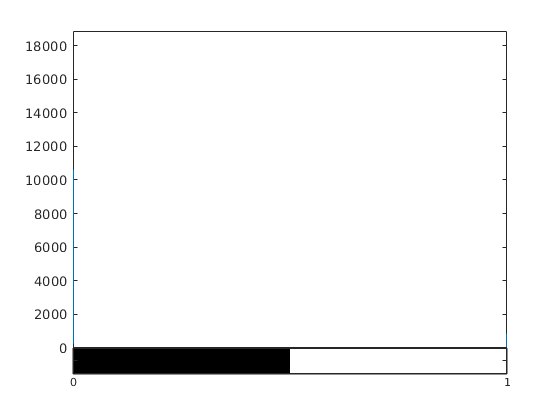

nrows = size(crystals, 1);
ncols = size(crystals, 2);
c_stp = ncols/3;

sec1 = imcrop( crystals, [0, 0, c_stp, nrows]);
sec2 = imcrop( crystals,[c_stp, 0, c_stp, nrows]);
sec3 = imcrop( crystals, [c_stp*2, 0, c_stp, nrows]);

figure,
imhist( crystals )

figure,
imshow( crystals )

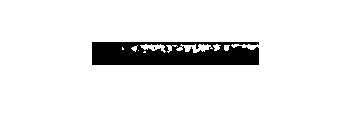

figure,
imshow(sec1)

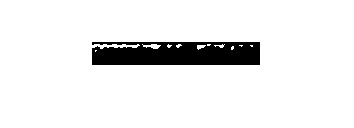

figure,
imshow(sec2)

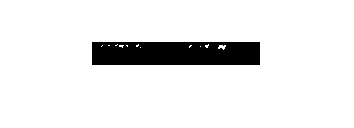

figure,
imshow(sec3)


[ counts, binLocations ] = imhist( crystals );
fprintf("The pixel crystals count for this image is: %i", counts(2) )

The pixel crystals count for this image is: 889